# Load data

if isfile('BI5_segments_HTS.mat')
    dataStruct = load('BI5_segments_HTS.mat');
else
    error('File BI5_segments_HTS.mat not found.');
end

segments = dataStruct.segments;
classes = dataStruct.classlabels;
t = dataStruct.t;
channels = dataStruct.ch_selection;

% find idx for each class. 1800 non-target, 400 target
idx_nontarget = find (classes == 1);
idx_target = find(classes == 2);

% get segments
segments_nontarget = segments(:, :, idx_nontarget);
segments_target = segments(:, :, idx_target);

% compute mean over the trials. We 3 channels and 77 time points, so
% result should be 3x77
mean_nontarget = mean(segments_nontarget, 3);
mean_target = mean(segments_target, 3);

# Ploting

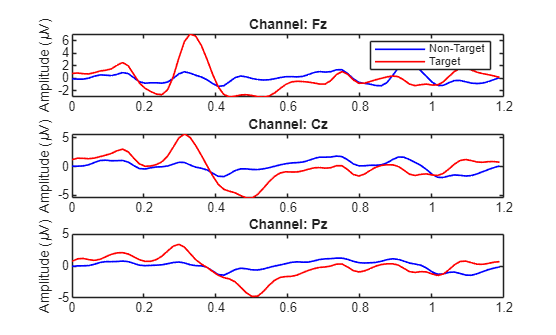

% Plot a figure for each channel with the two modalities (hold on).
figure('Name', 'P300 plot');

% Fz plot - just one legend
subplot(3, 1, 1);
plot(t, mean_nontarget(1, :), 'b', 'LineWidth', 1); 
hold on;
plot(t, mean_target(1, :), 'r', 'LineWidth', 1);
title(['Channel: ' channels{1}]);
ylabel('Amplitude (\muV)');
legend('Non-Target', 'Target');

% Cz
subplot(3, 1, 2);
plot(t, mean_nontarget(2, :), 'b', 'LineWidth', 1); 
hold on;
plot(t, mean_target(2, :), 'r', 'LineWidth', 1);
title(['Channel: ' channels{2}]);
ylabel('Amplitude (\muV)');

% Pz
subplot(3, 1, 3);
plot(t, mean_nontarget(3, :), 'b', 'LineWidth', 1); 
hold on;
plot(t, mean_target(3, :), 'r', 'LineWidth', 1);
title(['Channel: ' channels{3}]);
ylabel('Amplitude (\muV)');

% Compute max and min value across channels and conditions
max_val_target = max(mean_target, [], 2);
max_val_nontarget = max(mean_nontarget, [], 2);
min_val_target = min(mean_target, [], 2);

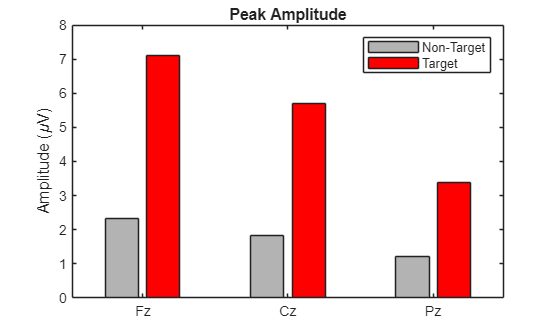

figure('Name', 'P300 Peak Amplitude');
bar_data = [max_val_nontarget, max_val_target]; 

b = bar(bar_data);
b(1).FaceColor = [0.7 0.7 0.7]; 
b(2).FaceColor = 'r';

xticklabels({'Fz', 'Cz', 'Pz'});
ylabel('Amplitude (\muV)');
legend('Non-Target', 'Target');
title('Peak Amplitude');